# Aula 5:

## Valor em Regime, Velocidade de um Sistema:

A partir de um sistema qualquer: 

Sys = tf(0.5,[1, -0.3], 0.1);

Podemos encontrar o valor em Regime para a Resposta Degrau através do teorema do valor final: 


$$R = \lim_{z\to1} (z - 1) \frac{z}{z-1} * \frac{0.5}{z - 0.3} = 0.7143
$$


E verificá-lo:

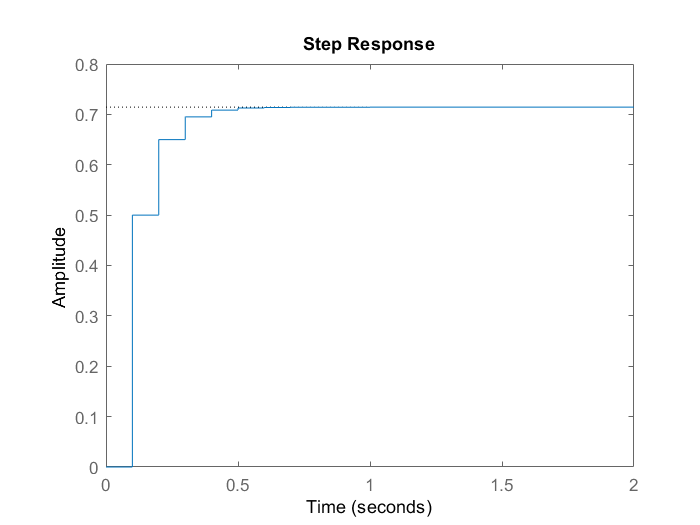

step(Sys)

Quanto à velocidade do sistema, podemos observar que, devido à resposta ao degrau possuir forma: 


$$Y(z) = \frac{z}{z-1} \frac{b_1z+b_0}{(z-r_1)(z-r_2)} $$


E, no tempo:


$$y[k] = Ar_1^k + Br_2^k+ C$$


Teremos um papel predominante do polo mais afastado de zero na rapidez do sistema. Entretanto, o valor complexo do polo está diretamente ligado à frequencia do sinal. Por exemplo: 

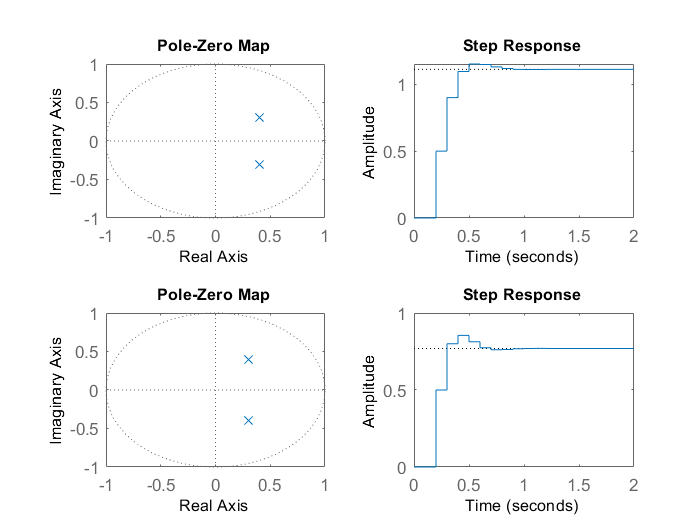

Sys1 = tf(0.5,[1,-0.8, 0.25], 0.1);
Sys2 = tf(0.5,[1,-0.6, 0.25], 0.1);
subplot(2,2, 1);
pzmap(Sys1);
subplot(2,2, 2);
step(Sys1);
subplot(2,2, 3);
pzmap(Sys2);
subplot(2,2, 4);
step(Sys2);

Ambos os sistemas estão à mesma distancia do centro, e por isso possuem a mesma velocidade, mas o segundo possui maior componente frequencial. O conceito ilustrado pode ainda ser visto nas demos. 